# Ejemplo de Discretización de Función de Transferencia


$$\textrm{Gp}\left(s\right)\longrightarrow \textrm{Gp}\left(z\right)$$



$$\mathrm{Gp}\left(z\right)=\left(1-z^{-1} \right)Z\left\lbrace \frac{\mathrm{Gp}\left(s\right)}{s}\right\rbrace$$


#### Ejemplo 1:


$$\mathrm{Gp}\left(s\right)=\frac{5}{10s+1}$$



$$\textrm{Gp}\left(z\right)=5-\frac{5\left(z-1\right)}{z-e^{-0\ldotp 1T} }$$


close all

s=tf('s');
Gps=5/(10*s+1)

Gps =
 
     5
  --------
  10 s + 1
 
Continuous-time transfer function.




T=0.1:3:10;
for i=1:length(T)
z=tf('z',T(i));
Gpz=5-5*(z-1)/(z-exp(-0.1*T(i)))
step(Gpz)
hold on
end

Gpz =
 
  0.04975
  --------
  z - 0.99
 
Sample time: 0.1 seconds
Discrete-time transfer function.

Gpz =
 
    1.333
  ----------
  z - 0.7334
 
Sample time: 3.1 seconds
Discrete-time transfer function.

Gpz =
 
    2.283
  ----------
  z - 0.5434
 
Sample time: 6.1 seconds
Discrete-time transfer function.

Gpz =
 
    2.987
  ----------
  z - 0.4025
 
Sample time: 9.1 seconds
Discrete-time transfer function.



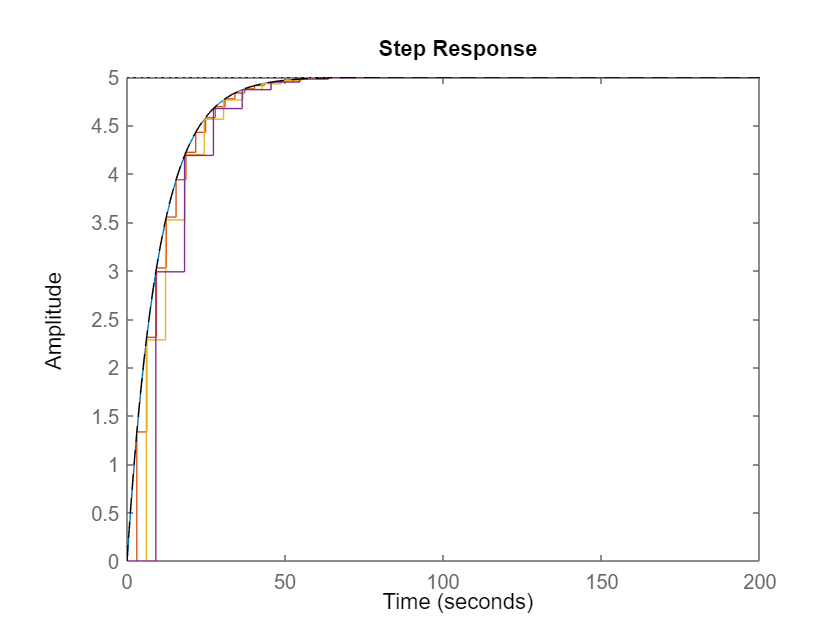


step(Gps,'k--')

#### Ejemplo 2:


$$\textrm{Gp}\left(s\right)=\frac{2s+4}{s^2 +2s+2}$$



$$\textrm{Gp}\left(z\right)=2-\frac{z-1}{z-e^{\left(i-1\right)T} }-\frac{z-1}{z-e^{-\left(i+1\right)T} }$$


clear all
close all

s=tf('s');
Gps=(2*s+4)/(s^2+2*s+2)

Gps =
 
     2 s + 4
  -------------
  s^2 + 2 s + 2
 
Continuous-time transfer function.




T=0.25

T = 0.2500

z=tf('z',T);
Gpz=2 - (z-1)/(z-exp((i-1)*T)) - (z-1)/(z-exp(-(i+1)*T))

Gpz =
 
  0.4908 z - (0.2961-2.776e-17i)
  ------------------------------
      z^2 - 1.509 z + 0.6065
 
Sample time: 0.25 seconds
Discrete-time transfer function.



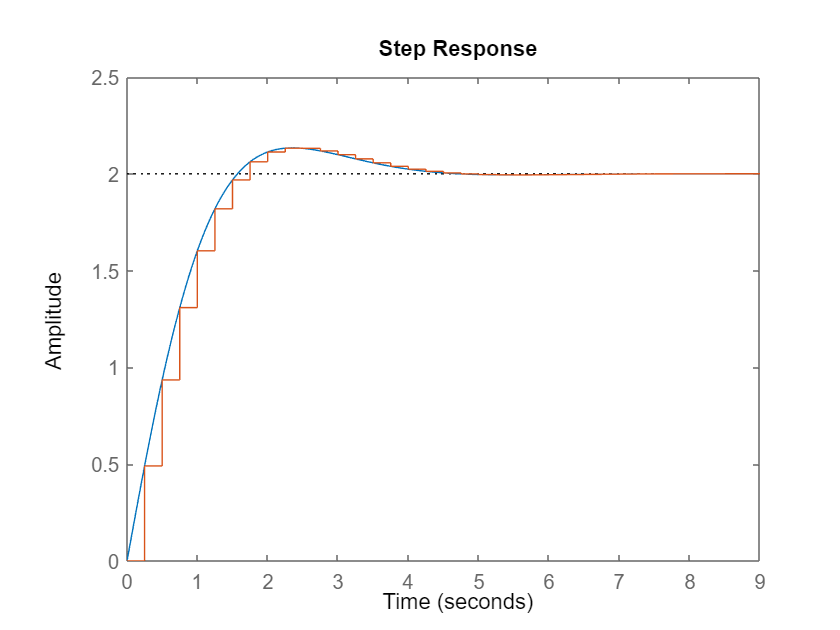


step(Gps)
hold on
step(Gpz)